# 中心極限定理の確認

## 1．一様分布の場合

### 分布オブジェクトの生成

例として、平均 1.7 の指数分布オブジェクトを作成する。

pd1 = makedist("Uniform", "lower",0, "upper",2);

### 乱数の生成と正規分布によるフィッティング

乱数を生成し、ヒストグラムを描画する

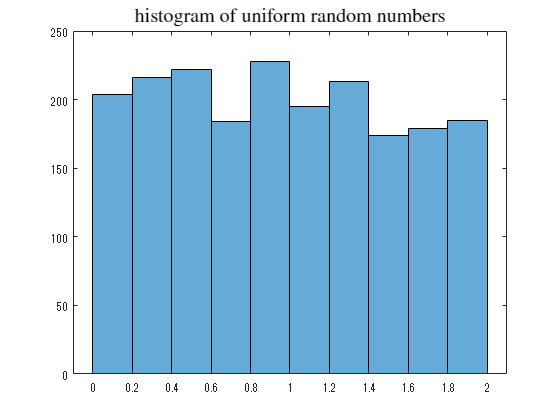

rd1 = random(pd1,[10000 2000]);
histogram(rd1(1,:))
title('histogram of uniform random numbers', Interpreter='latex', FontSize=15)

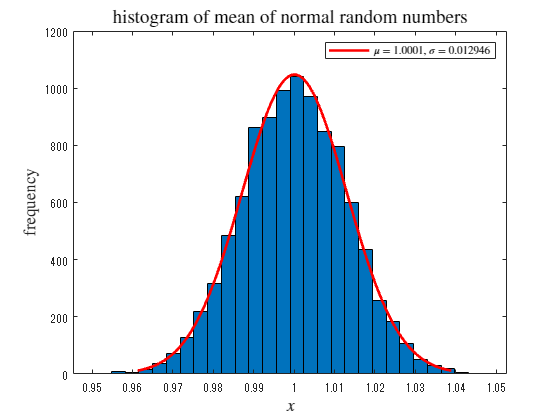



rd1m = mean(rd1(1:10000, :), 2);
fc1 = fitdist(rd1m,"normal");
hc1 = histfit(rd1m, 30,"normal");
hc12 = hc1(2);
set(hc12, DisplayName="$\mu =$"+string(fc1.mu)+", $\sigma =$"+string(fc1.std))
title('histogram of mean of normal random numbers', Interpreter='latex', FontSize=14)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("frequency", Interpreter="latex", FontSize=13)
legend(hc12, Interpreter="latex")

## 2．指数分布の場合

### 分布オブジェクトの生成

例として、平均 1.7 の指数分布オブジェクトを作成する。

pd2 = makedist("Exponential", mu=1.7);

### 乱数の生成と正規分布によるフィッティング

乱数を生成し、ヒストグラムを描画する

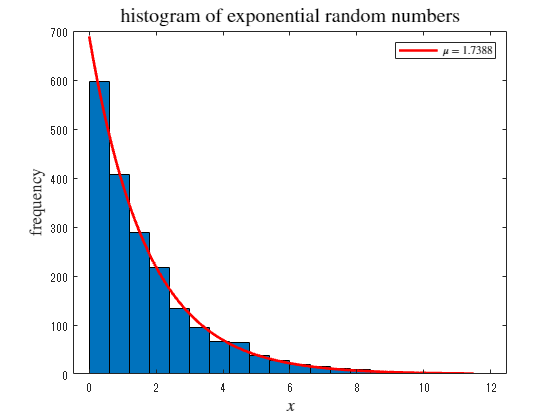

rd2 = random(pd2,[10000 2000]);
h2 = histfit(rd2(1,:), 20, "exponential");
f2 = fitdist(rd2(1,:)',"exponential");
h22 = h2(2);
set(h22, DisplayName="$\mu =$"+string(f2.mu))
title('histogram of exponential random numbers', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("frequency", Interpreter="latex", FontSize=13)
legend(h22, Interpreter="latex")

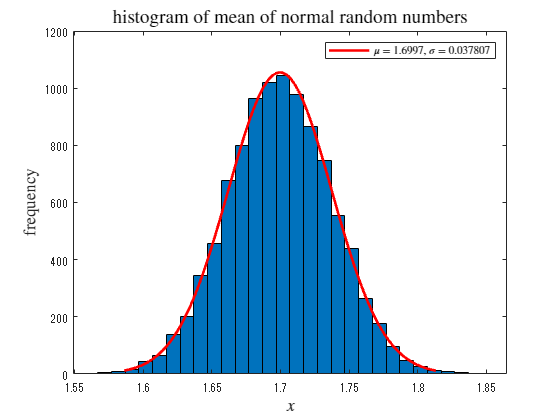



rd2m = mean(rd2(1:10000, :), 2);
fc2 = fitdist(rd2m,"normal");
hc2 = histfit(rd2m, 30,"normal");
hc22 = hc2(2);
set(hc22, DisplayName="$\mu =$"+string(fc2.mu)+", $\sigma =$"+string(fc2.std))
title('histogram of mean of normal random numbers', Interpreter='latex', FontSize=14)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("frequency", Interpreter="latex", FontSize=13)
legend(hc22, Interpreter="latex")